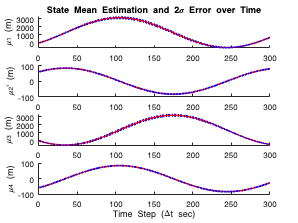

% ASEN 5044
% HWK 7
clear
omega = 0.045;
dt = 0.5;

A = [0 1 0 0 ; 0 0 0 -omega; 0 0 0 1; 0 omega 0 0 ];

F = [1 (sin(omega*dt))/omega 0 -(1-cos(omega*dt))/omega; 
    0 cos(omega * dt) 0 -sin(omega*dt); 
    0 (1-cos(omega*dt))/omega 1 (sin(omega*dt))/omega;
    0 sin(omega*dt) 0 cos(omega*dt)];

PArr = []; xhatArr = []; 
sigma = [];

M = [0; 85*cos(pi/4); 0; -82*sin(pi/4)];
p0 = [10 2 10 2]';
P0 = diag(p0);
PArr(:,:,1) = P0;
xhatArr(:,:,1) = M;

for k = 1:300
   sigma(:,k) = 2 * sqrt(diag(P0));
   P0 =  F * P0 * F';
   PArr(:,:,k+1) = P0;
   M = F*M;
   xhatArr = [xhatArr M];
end

% Plot the results.
close all; % close all figures
figure; % open a new figure
set(gcf,'Color','white');
k = 1 : 300;
subplot(4,1,1); hold on;
plot(k, xhatArr(1,1:300), 'r-', 'LineWidth', 2);
plot(k, sigma(1,:) + xhatArr(1,1:300), 'b:' )
plot(k, -sigma(1,:) + xhatArr(1,1:300), 'b:' )
set(gca,'FontSize',10);
title('State Mean Estimation and 2\sigma Error over Time');
ylabel('\mu_1 (m)')

subplot(4,1,2); hold on;
plot(k, xhatArr(2,1:300), 'r-', 'LineWidth', 2);
plot(k, sigma(2,:) + xhatArr(2,1:300), 'b:' )
plot(k, -sigma(2,:) + xhatArr(2,1:300), 'b:' )
set(gca,'FontSize',10);
ylabel('\mu_2'' (m)')

subplot(4,1,3); hold on;
plot(k, xhatArr(3,1:300), 'r-', 'LineWidth', 2);
plot(k, sigma(3,:) + xhatArr(3,1:300), 'b:' )
plot(k, -sigma(3,:) + xhatArr(3,1:300), 'b:' )
set(gca,'FontSize',10);
ylabel('\mu_3 (m)')

subplot(4,1,4); hold on;
plot(k, xhatArr(4,1:300), 'r-', 'LineWidth', 2);
plot(k, sigma(4,:) + xhatArr(4,1:300), 'b:' )
plot(k, -sigma(4,:) + xhatArr(4,1:300), 'b:' )
set(gca,'FontSize',10);
ylabel('\mu_4 (m)'); xlabel('Time Step (\Deltat sec)')
hold off

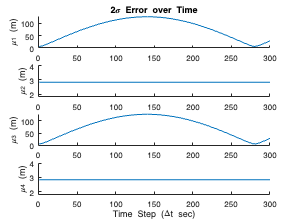

% plot 2 sigma only
figure; % open a new figure
set(gcf,'Color','white');
k = 1 : 300;
subplot(4,1,1); hold on;
plot(k, sigma(1,:) )
set(gca,'FontSize',10);
title('2\sigma Error over Time');
ylabel('\mu_1 (m)')

subplot(4,1,2); hold on;
plot(k, sigma(2,:) )
set(gca,'FontSize',10);
ylabel('\mu_2 (m)')

subplot(4,1,3); hold on;
plot(k, sigma(3,:) )
set(gca,'FontSize',10);
ylabel('\mu_3 (m)')

subplot(4,1,4); hold on;
plot(k, sigma(4,:)  )
set(gca,'FontSize',10);
ylabel('\mu_4 (m)'); xlabel('Time Step (\Deltat sec)')
hold off;

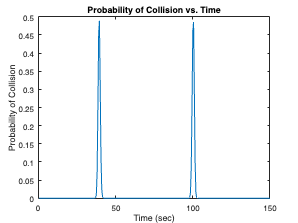

%%%%%%
% problem 3
%%%%%%
% define rectangle for mvncdf function
xl = [-100 -100];
xu = [100 100];
PArra = []; xhatArra = []; sigmaa = [];
PArrb = []; xhatArrb = []; sigmab = [];
oma = 0.045;
omb = -0.045;
Fa = [1 (sin(oma*dt))/oma 0 -(1-cos(oma*dt))/oma; 
    0 cos(oma * dt) 0 -sin(oma*dt); 
    0 (1-cos(oma*dt))/oma 1 (sin(oma*dt))/oma;
    0 sin(oma*dt) 0 cos(oma*dt)];

Fb = [1 (sin(omb*dt))/omb 0 -(1-cos(omb*dt))/omb; 
    0 cos(omb * dt) 0 -sin(omb*dt); 
    0 (1-cos(omb*dt))/omb 1 (sin(omb*dt))/omb;
    0 sin(omb*dt) 0 cos(omb*dt)];

Ma = [0 85*cos(pi/4) 0 -85*sin(pi/4)]';
ma = Ma;
pa = [10;4;10;4];
Pa = diag(pa);

Mb =  [3200 85*cos(pi/4) 3200 -85*sin(pi/4)]';
mb = Mb;
pb = [11;3.5;11;3.5];
Pb = diag(pb);

xhatArra(:,:,1) = Ma;
xhatArrb(:,:,1) = Mb;

% calculate mean position for each aircraft
for k = 1:300
   Ma = Fa*Ma;
   xhatArra = [xhatArra Ma];
   Mb = Fb*Mb;
   xhatArrb = [xhatArrb Mb];   
end

% Calculate covariance, mean and probability of collision
for k = 1:300
   Pc  =  Fa^k * diag(pa) * Fa^k' + Fb^k*diag(pb) * Fb^k';
   M =  Fa^k*ma - Fb^k*mb;
   % remove 2nd and 4th row/column to marginalize
   mr = [M(1,1) M(3,1)];
   pr = [Pc(1:1,1:1) Pc(1:1,3:3); Pc(1:1,3:3) Pc(3:3,3:3)];
   Pr(:,k) = mvncdf(xl, xu, mr, pr);
end

figure
plot((.5:.5:150),Pr)
title('Probability of Collision vs. Time')
xlabel('Time (sec)'); ylabel('Probability of Collision')
set(gca,'FontSize',10);

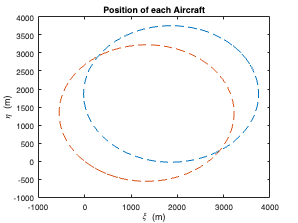


% Plot positions of aircrafts
plot(xhatArrb(1:1,:),xhatArrb(3:3,:),'--',xhatArra(1:1,:),xhatArra(3:3,:),'--')
title('Position of each Aircraft')
ylabel('\eta (m)') ;xlabel('\xi (m)')
set(gca,'FontSize',10);